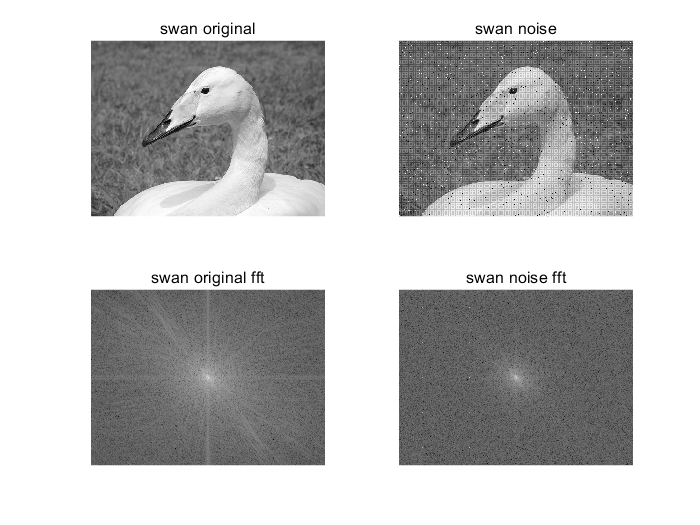

% 原始图像与噪声图像
swan_original = imread("swanOriginal.bmp");
swan_noise = imread("swanNoise.bmp");

subplot(2,2,1);imshow(swan_original);title("swan original");
subplot(2,2,2);imshow(swan_noise);title("swan noise");

% 频谱图
swan_original_fft = fftshift(fft2(swan_original));
swan_noise_fft = fftshift(fft2(swan_noise));

subplot(2,2,3);imshow(mat2gray(log(1+abs(swan_original_fft))));title("swan original fft");
subplot(2,2,4);imshow(mat2gray(log(1+abs(swan_noise_fft))));title("swan noise fft");

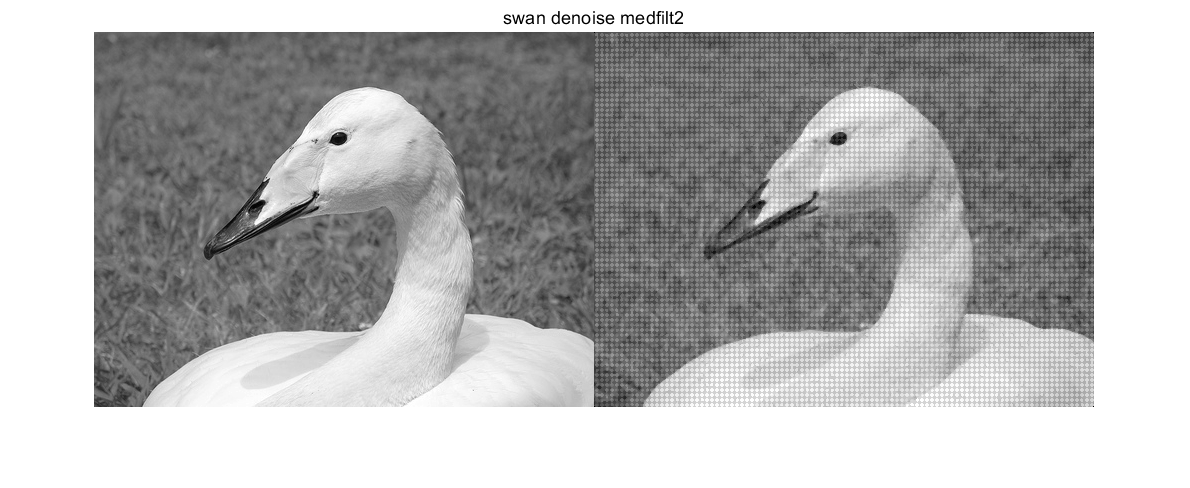

% medfilt2 二维中值滤波
% https://ww2.mathworks.cn/help/images/ref/medfilt2.html

swan_denoise_by_medfilt2 = medfilt2(swan_noise,[3,3]);

figure;
imshowpair(swan_original,swan_denoise_by_medfilt2,"montage");
title("swan denoise medfilt2");

display("mse = " + immse(swan_original,swan_denoise_by_medfilt2));

    "mse = 528.792"



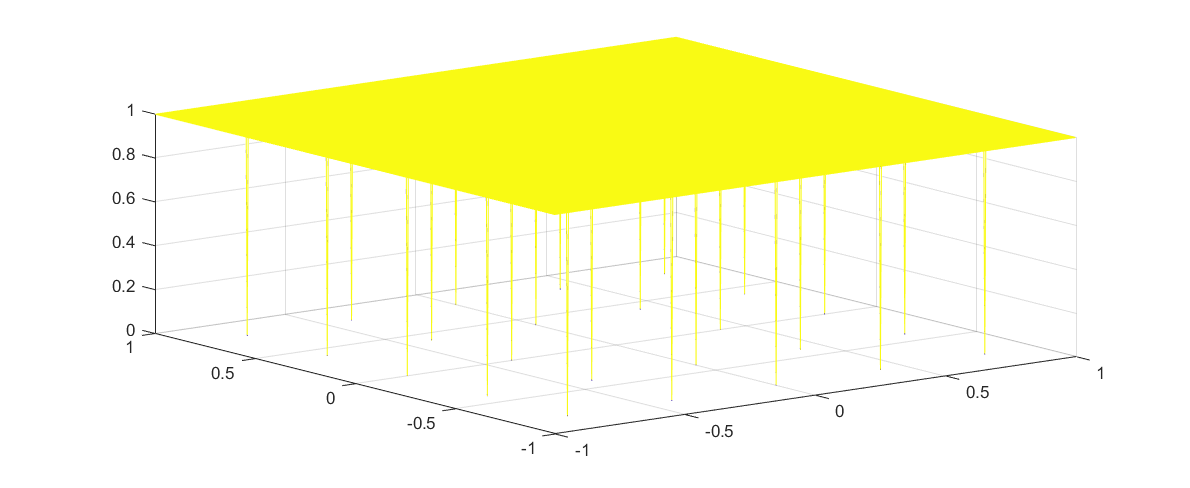

% 陷波滤波器
% 手动构造

[m,n] = size(swan_noise);
[f1,f2] = freqspace([m,n],'meshgrid');
Hd = ones([m,n]);

for x=1:m
    for y=1:n
        dx = x - floor(m/2);
        dy = y - floor(n/2);
        if dx==0 && dy == 0
            continue;
        end
        if mod(dx,floor(m/5))==0 && mod(dy,floor(n/5))==0
           % Hd(x-1:x+1,y-1:y+1) = 0;
           % Hd(x,y) = 0;
           Hd(x+1,y+1)=0;
        end
    end
end

mesh(f1,f2,Hd);

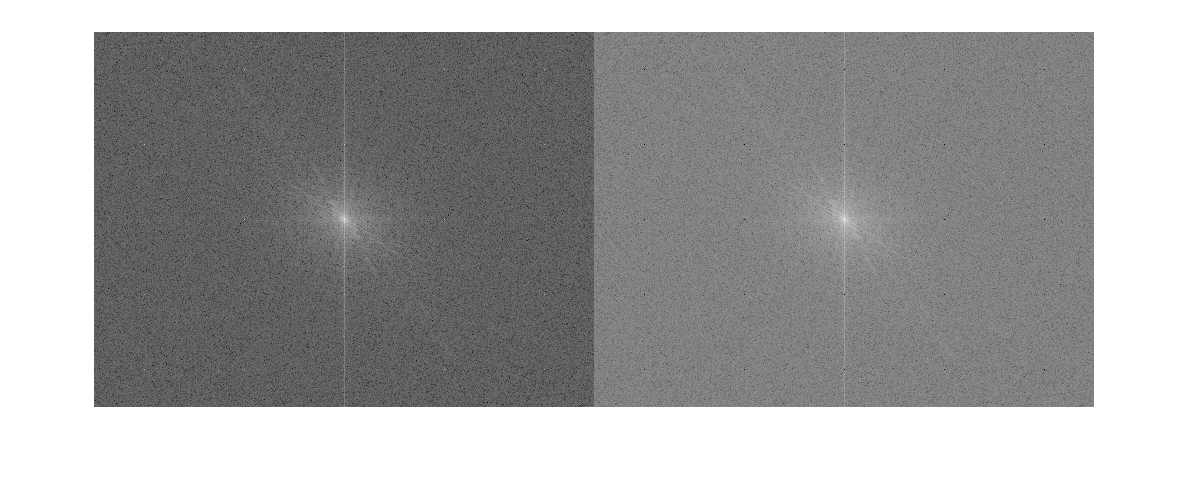


swan_denoise_by_notch_fft = swan_noise_fft .* Hd;
imshowpair( ...
    mat2gray(log(1+abs(swan_noise_fft))), ...
    mat2gray(log(1+abs(swan_denoise_by_notch_fft))), ...
    "montage" ...
);

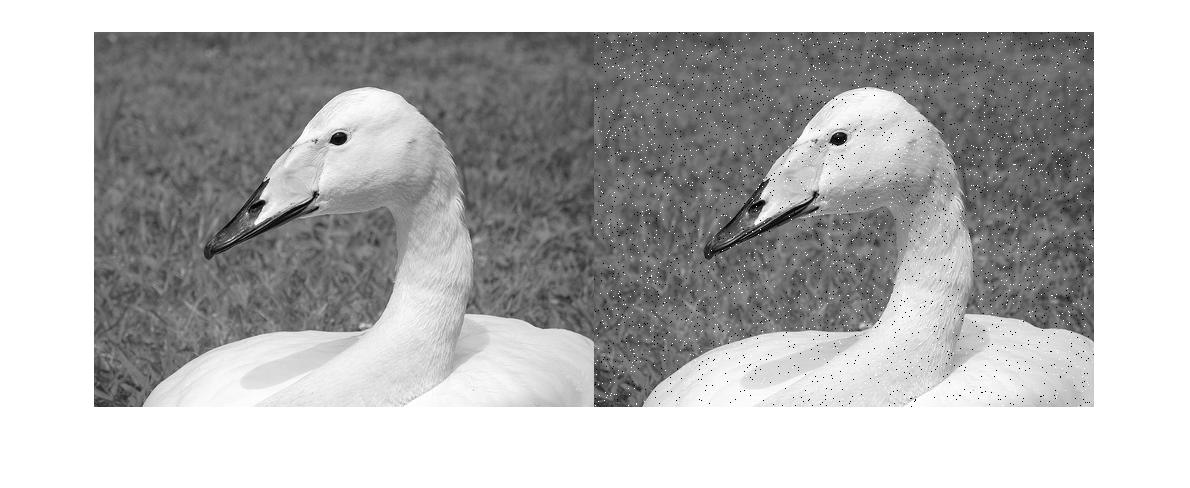


swan_denoise_by_notch = uint8(round(real(ifft2(ifftshift(swan_denoise_by_notch_fft)))));

imshowpair(swan_original, swan_denoise_by_notch, "montage");

display("mse = " + immse(swan_original,swan_denoise_by_notch));

    "mse = 459.2805"



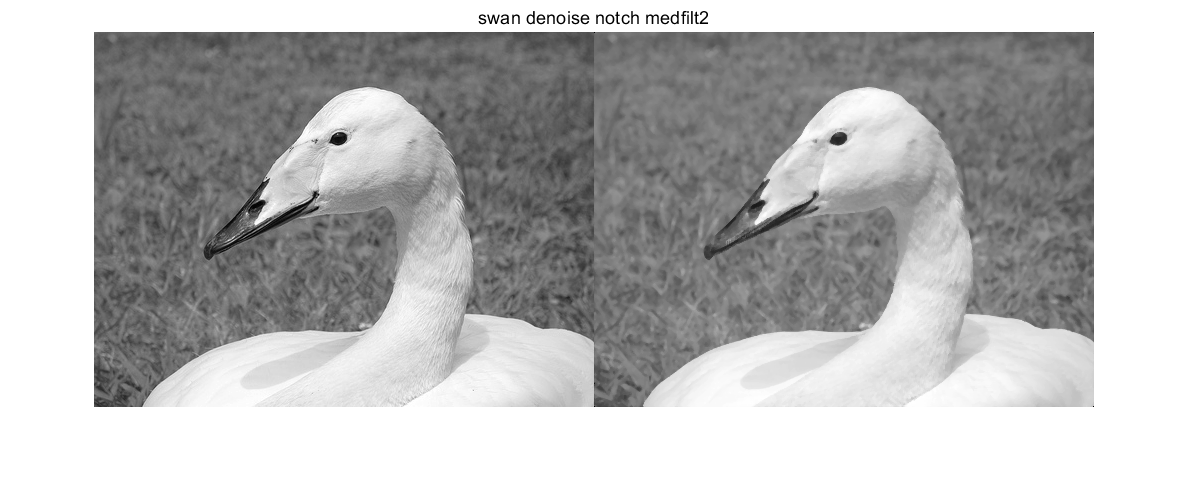

% 陷波滤波 -> 中值滤波
swan_denoise_try1 = medfilt2(swan_denoise_by_notch,[3 3]);

imshowpair(swan_original, swan_denoise_try1, "montage");
title("swan denoise notch medfilt2");

display("mse = " + immse(swan_original,swan_denoise_try1));

    "mse = 207.4607"



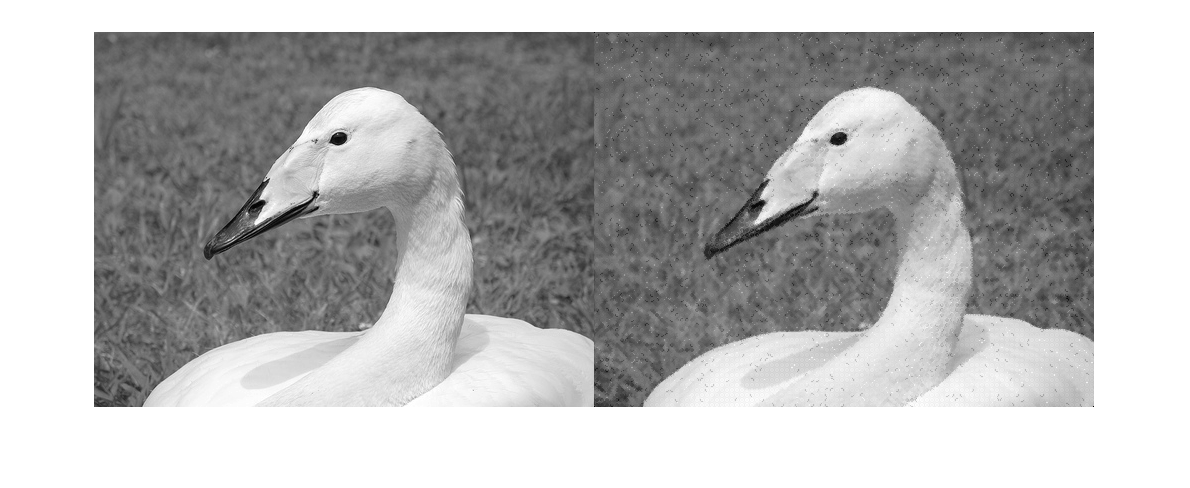

% 中值滤波 -> 陷波滤波
swan_denoise_try2_fft = fftshift(fft2(swan_denoise_by_medfilt2));
swan_denoise_try2 = uint8(round(real(ifft2(ifftshift(swan_denoise_try2_fft .* Hd)))));

imshowpair(swan_original, swan_denoise_try2, "montage");

display("mse = " + immse(swan_original,swan_denoise_try2));

    "mse = 254.1549"

